# 1. Single-step cavity circuit test - MATLAB

Run cavity_circuit_test.ipynb first, then Run All here. This .m and its .mlx companion contain the same test. Raw inputs -> Gaussian maps -> grid -> prescribed beam -> global circuit. No Python solution is loaded, and no full solver/app is launched. Reconstructed operating fields are TEST-ONLY diagnostics, not a repair of the original solver's Emz update. No beam dynamics or space charge.

test_directory = fileparts(mfilename('fullpath'));
if ~isfile(fullfile(test_directory, 'cavity_circuit_test.m'))
    test_file = matlab.desktop.editor.getActiveFilename;
    test_directory = fileparts(test_file);
    if ~isfile(fullfile(test_directory, 'cavity_circuit_test.m'))
        test_directory = fileparts(which('cavity_circuit_test.m'));
    end
end
input_file = fullfile(test_directory, 'inputs.mat');
assert(isfile(input_file), ...
    'Cannot find inputs.mat at: %s\nRun cavity_circuit_test.ipynb first.', input_file);
load(input_file);
assert(Nr == 1 && N == 200 && mono == 1);
assert(all(Ut == Ut(1)) && all(Lsb == pi));
assert(all(nh >= 1 & nh <= Ns) && all(ismember(type,[-1,0,1])));
assert(all(Qext > 0) && all(Qin > 0) && all(Pin >= 0));
assert(all(M > 0 & M < 1) && all(RtoQ > 0) && all(abs(gaman) < 1));
assert(all(kai == 0 | nh' == nh,'all'));
N_input = N; % Gaussian app code below reuses N as a vector.

% Minimal GUI-value fixture for the copied Gaussian branch.
app = struct();
app.BeamVolEF.Value = Ut(1);
app.Switch_2.Value = 'GS';
app.UITable_2.Data = zeros(Nc,1);
z_mm = zeros(N+1,Nc);
e_z = zeros(N+1,Nc);

## 2. Gaussian profiles - Original KlyC_v6.mlapp code

Copied from matlab/document.xml lines 1655-1692. Gaussian arithmetic, constants, sign(Qext) and Nr replication are unchanged. The text-file save is replaced by snapshots z_mm/e_z, one column per cavity. The trailing end replaces the omitted non-Gaussian else branch.

                U0=app.BeamVolEF.Value; % kV
                c=299792458;  % m/s, light speed
                eta0=4E-7*pi*c; % ohm, wave impendance of TEM
                etom=1.7588E11;  % C/kg, charge to mass of electron
                s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
                k0=2*pi*f0*1E9/c; % 1/m
                w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant

                S1=regexp(cavityname,'\s+','split');


                zminarray=zeros(1,Nc);
                zmaxarray=zeros(1,Nc);
                EMflag=0; % to determine whether all the EM solvers are successfully done
                Emax=zeros(1,Nc); % kV/mm, store the maximum electric field with stored energy of 1J
                kais=zeros(4,Nc);% to store the normalized self-calculated kai elements for each cavity
                rcEMs=rc*ones(2,Nc); % mm,to store the beam aperture at the left side and right side of each cavity


                if strcmp(app.Switch_2.Value,'GS')==1  % Guassian profile will be adopted
                    N=200*ones(1,Nc); % number of points,, for Guassian and uniform
                    for kk=1:Nc
                        if M(kk)>0 % To forbid the collapse by non-positive number
                            k=0.5*w0(kk)/s/c/sqrt(-log(M(kk))); % 1/m
                            ezm=(RtoQ(kk)/eta0/pi*k0(kk)*k*k)^0.5*(1000)^(-3/2); % mm^(-3/2)
                            z=[-1/k*3:2*1/k*3/N(kk):1/k*3]'*1000; %mm
                            zminarray(kk)=-1/k*3*1000+zshift(kk);
                            zmaxarray(kk)=1/k*3*1000+zshift(kk);
                            ez=ezm*exp(-k*1E-3*k*1E-3*z.*z); % mm^(-3/2)
                            ezr=repmat(ez,1,Nr);
                            cavity=[z ezr*sign(Qext(kk))];
                            % TEST ONLY: retain maps in memory instead of saving TXT.
                            z_mm(:,kk)=cavity(:,1);
                            e_z(:,kk)=cavity(:,2);
                            Emax(kk)=abs(app.UITable_2.Data(kk,1));
                            if nh(kk)>0
                                EMflag=EMflag+1;
                            end
                        end
                    end
                end

## 3. Reference beam and solver grid - Original KLJCmainsv22.m lines 45-86

This block independently calculates the grid from raw inputs. k0 is now in 1/mm (the app's k0 above was in 1/m). The space-charge source-window block is not needed for this field test.

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 256


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence

## 4. Shift, pad, interpolate and normalize - Original lines 100-129

Only the original A=load(...) line is adapted to use the Gaussian arrays. Shifting, padding, interpolation and normalization below are unchanged. TEST ONLY: restore solver units if k0 still has the app's value in 1/m. Recompute from w0, rather than dividing the existing k0 again on each run.

k0=w0/c/1000; % 1/mm, consistent with zi and the field normalization

ez=zeros(length(zi),Nc); % mm^(-3/2),normalized electric field stored or coupling impedance /ohm
C3=ez*0;
vpz=ez*0;
alfaz=ez*0;
S=regexp(cavityname,'\s+','split');


for k=1:Nc % For every cavity
    if nh(k)>Ns % If the cavity 
        continue;
    end
    A=[z_mm(:,k),e_z(:,k)]; % TEST ONLY: Gaussian map instead of TXT load
    A(:,1)=A(:,1)+zshift(k);
    if min(A(:,1))<=z0+dz/10 || max(A(:,1))>=z0+L-dz/10
        fprintf('warning: the emission plate is located in the field margin of ');
        fprintf('cavity number ');fprintf(num2str(k));fprintf('\n');
    end
    
    if type(k)~=2
        AA=[A(1,1)-2*dz/10,0;A(1,1)-dz/10,0;A;A(length(A(:,1)),1)+dz/10,0;A(length(A(:,1)),1)+2*dz/10,0];
        ez(:,k)=interp1(AA(:,1),AA(:,2),zi,'linear','extrap'); % mm^(-3/2), normalized e-field sequence; or kV/mm, DC e-field
        if nh(k)==0
            C3(:,k)=(ez(:,k)/betae/U0);    % for normalized DC E-field
        else
            C3(:,k)=(ez(:,k)*eta0*I0/k0(k)^(1/2)/betae/U0/1000);
        end
    else

    end
end

## 5. Normalized coordinates - Original lines 132-133

z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron

## 6. Initialize beam harmonics - Original lines 136-149 and 157-159

Plasma frequency and space-charge code are outside this test.

Iz=zeros(length(z),Ns);
QQ=zeros(length(z),Ns);

% intial value given
Y=Y0;
IzDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0)*ones(length(z),1); % normalized DC current along the axis
for k=1:Ns
    Iz(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)))*ones(length(z),1); % normalized,intial modulated current of 1st harmonic
end

QQDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*vn1(Y))*ones(length(z),1); % DC charge density along axis
for k=1:Ns
    QQ(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)).*vn1(Y))*ones(length(z),1); % normalized,intial modulated charged density
end

effe=0*ones(length(z),1); % if all electron reflected, the efficiency will be 100%
vez=1*ones(length(z),1); % ve/ve0
gamaz=(1-(vez*s).^2).^(-1/2);

## 7. TEST ONLY: prescribed constant-speed transport

The original initialization is longitudinally constant. This analytic phase advance is NOT a response to the solved cavity fields.

if strcmp(beam_transport,'constant_speed')
    phase_advance = exp(-1i*(z-z(1))*(1:Ns));
    Iz = Iz.*phase_advance;
    QQ = QQ.*phase_advance;
else
    assert(strcmp(beam_transport,'initial_guess'));
end

## 8. Circuit initialization - Original lines 183-187 and 207

flagVnc=zeros(1,Nc);  % record the mode voltage
effendflag=0;
Pinflag=sign(Pin); % if Pin is negative, BW analysis will be adopted in TW analysis
Pin=abs(Pin); % W, Pin itself should be a positive number
Vin=(Pin/U0/1000/Nbeam/I0).^0.5.*(2*Nbeam*I0/U0/1000*eta0).^0.5;% normalized mode voltage of TE10
kai=kai*mono; % coupling analysis is not supported in monotron oscillation

## 9. One global circuit assembly/solve - Original lines 219-291

The outer nn loop is not run. nn and ramp settings are raw test inputs. mono=1 selects the fixed-frequency branch. Original arithmetic unchanged.

    Vnp=zeros(1,Nc); % normalized waveguide voltage * sqrt(eta0/z0)
    Vnc=zeros(1,Nc);
    
    
    Mc=zeros(2*Nc,2*Nc);
    B=zeros(2*Nc,1);
    
    for k=1:Nc
        
        if type(k)==-1 && nh(k)<=Ns % FOR OUTPUT CAVITY
            B((2*k-1):(2*k))=[0;-esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)))];
            Mc(2*k-1,2*k-1)=sqrt(Qext(k))*(gaman(k)*exp(1i*Lsb(k))+exp(-1i*Lsb(k)));
            Mc(2*k,2*k-1)=sqrt(1/Qext(k))*(gaman(k)*exp(1i*Lsb(k))-exp(-1i*Lsb(k)));
            Mc(2*k-1,2*k)=-1;
            if mono==0 && nn>1
                dfmono=imag(B(2*k))/real(B(2*k))*(-1/Qin(k)+real(Mc(2*k,2*k-1)/Mc(2*k-1,2*k-1)))-imag(Mc(2*k,2*k-1)/Mc(2*k-1,2*k-1)); % To make sure Vnc is positive number
                ws=(dfmono/(-2)*w0(k)+w0(k))/nh(k);
                wsp=[wsp,ws];
                % disp(ws/2/pi*1E-9);
                
                Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*ws-w0(k))/w0(k)+1i*2*kai(k,k));
            else
                Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*w-w0(k))/w0(k)+1i*2*kai(k,k));
            end
            if k<Nc
                Mc(2*k,2*(k+1):2:2*Nc)=-1i*kai(k,(k+1):Nc);
            end
            if k>1
                Mc(2*k,2:2:2*(k-1))=-1i*kai(k,1:(k-1));
            end
            
            
        elseif type(k)==0  && nh(k)<=Ns % FOR INPUT CAVITY
            Mc(2*k-1,2*k-1)=sqrt(Qext(k))*exp(-1i*Lsb(k));
            Mc(2*k,2*k-1)=sqrt(1/Qext(k))*(-exp(-1i*Lsb(k)));
            Mc(2*k-1,2*k)=-1;
            Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*w-w0(k))/w0(k)+1i*2*kai(k,k));
            if k<Nc
                Mc(2*k,2*(k+1):2:2*Nc)=-1i*kai(k,(k+1):Nc);
            end
            if k>1
                Mc(2*k,2:2:2*(k-1))=-1i*kai(k,1:(k-1));
            end
            B((2*k-1):(2*k))=[-sqrt(Qext(k))*exp(1i*Lsb(k))*Vin(k)*max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)));-esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)))-sqrt(1/Qext(k))*exp(1i*Lsb(k))*Vin(k)*max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)))];
            
        elseif type(k)==1 && nh(k)<=Ns && nh(k)>=1 % FOR BUNCH CAVITY
            Mc(2*k-1,2*k-1)=1;
            Mc(2*k,2*k-1)=0;
            Mc(2*k-1,2*k)=0;
            Mc(2*k,2*k)=-(1/Qin(k)+1i*2*(nh(k)*w-w0(k))/w0(k)+1i*2*kai(k,k));
            if k<Nc
                Mc(2*k,2*(k+1):2:2*Nc)=-1i*kai(k,(k+1):Nc);
            end
            if k>1
                Mc(2*k,2:2:2*(k-1))=-1i*kai(k,1:(k-1));
            end
            B((2*k-1):(2*k))=[0;-esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)))]; % n-harmonic current stimulation
            
            
        else
            Mc(2*k-1,2*k-1)=1;
            Mc(2*k,2*k-1)=0;
            Mc(2*k-1,2*k)=0;
            Mc(2*k,2*k)=1;
            B((2*k-1):(2*k))=[0;0];
        end
        
    end
    
    
    temp=Mc\B;
    Vnp=temp(1:2:(2*Nc)).'; % normalized voltage for output microwave
    Vnc=temp(2:2:(2*Nc)).'; % normalized voltage for cavity mode

## 10. TEST ONLY: dimensional field reconstruction and power diagnostics

Copied gap-voltage line 674 (identical RF expression at 682 and 692). Applied to all supported RF cavities. This is not the original Emz update.

Ibeam = zeros(1,Nc);
Vng = zeros(1,Nc);
Ezc = zeros(length(z),Nc);
Emz_reconstructed = zeros(length(z),Ns);
for k=1:Nc
    Ibeam(k) = -esign*Nbeam*trapz(z,C3(:,k).*Iz(:,nh(k)));
        Vng(k)=U0*Vnc(k)*k0(k)^(-1/2)*trapz(zi,ez(:,k));
    Ezc(:,k) = U0*Vnc(k)/sqrt(k0(k))*ez(:,k); % kV/mm
    Emz_reconstructed(:,nh(k)) = Emz_reconstructed(:,nh(k)) + Ezc(:,k)/betae/U0;
end
Ezt = betae*U0*imag(Emz_reconstructed*exp(1i*(1:Ns)'*theta));
power_scale = (U0*1000)^2/(2*eta0);
Pport = power_scale*abs(Vnp).^2;
Pwall = power_scale*abs(Vnc).^2./Qin;
Pout = zeros(1,Nc);
Pout(type == -1) = (1-abs(gaman(type == -1)).^2).*Pport(type == -1);
RtoQ_grid = eta0./k0.*abs(trapz(zi,ez,1)).^2;
drivefactor = max(sqrt(min(1/Npin*(floor(2*nn/Nlimit*Npin)+1),1)),abs(sign(abs(moviedisp(4))-2)));
N = N_input; % Restore scalar Gaussian interval count for comparison.

disp(table(S1',type',Ibeam.',Vnp.',Vnc.',Vng.',Pwall',Pout', ...
    'VariableNames',{'Cavity','Type','Ibeam','Vnp','Vnc','Vng_kV','Pwall_W','Pout_W'}));

          Cavity          Type           Ibeam                   Vnp                 Vnc               Vng_kV          Pwall_W        Pout_W  
    __________________    ____    ____________________    _________________    ________________    _______________    __________    __________

    {'guide_cavity_1'}      0       0.027782+0.021071i     0.49875+0.37741i    -9.1365-6.8974i     -1145.9-865.04i    3.4303e+05             0
    {'guide_cavity_2'}      1     -0.0042745-0.026693i           0+0i          -2.2362+0.36783i    -224.31+36.897i         11172             0
    {'guide_cavity_3'}      1       0.022961+0.003804i           0+0i          0.11961-0.72921i     11.206-68.316i          1185             0
    {'guide_

disp('Ezc is kV/mm (= MV/m); Emz_reconstructed is dimensionless.');

Ezc is kV/mm (= MV/m); Emz_reconstructed is dimensionless.


disp('Pport is reflected input power or outgoing output power, depending on type.');

Pport is reflected input power or outgoing output power, depending on type.


disp('This prescribed-beam result is not a converged output-power prediction.');

This prescribed-beam result is not a converged output-power prediction.


## 11. TEST ONLY: inspect beam, matrix, voltages and fields

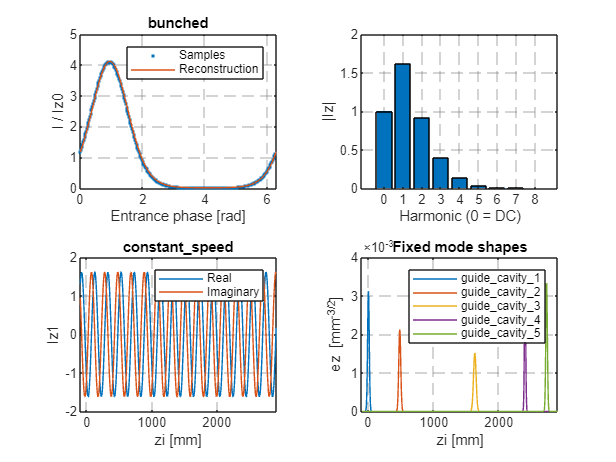

style_axes = @(fig) set(findall(fig,'Type','axes'), ...
    'XGrid','on','YGrid','on','GridLineStyle','--', ...
    'GridColor',[0.5 0.5 0.5],'GridAlpha',0.45);
phase_plot = linspace(0,2*pi,600)';
current_waveform = IzDC(1)+imag(exp(1i*phase_plot*(1:Ns))*Iz(1,:).');
figure('Name','Prescribed beam and fixed mode shapes');
tiledlayout(2,2);
nexttile; plot(mod(tn1,2*pi),Izt/Iz0,'.',phase_plot,current_waveform,'-');
xlabel('Entrance phase [rad]'); ylabel('I / Iz0');
title(case_name,'Interpreter','none'); legend('Samples','Reconstruction');
nexttile; bar(0:Ns,abs([IzDC(1),Iz(1,:)]));
xlabel('Harmonic (0 = DC)'); ylabel('|Iz|');
nexttile; plot(zi,real(Iz(:,1)),zi,imag(Iz(:,1)));
xlabel('zi [mm]'); ylabel('Iz1'); legend('Real','Imaginary');
title(beam_transport,'Interpreter','none');
nexttile; plot(zi,ez); xlabel('zi [mm]'); ylabel('ez [mm^{-3/2}]');
title('Fixed mode shapes'); legend(S1,'Interpreter','none');
style_axes(gcf);

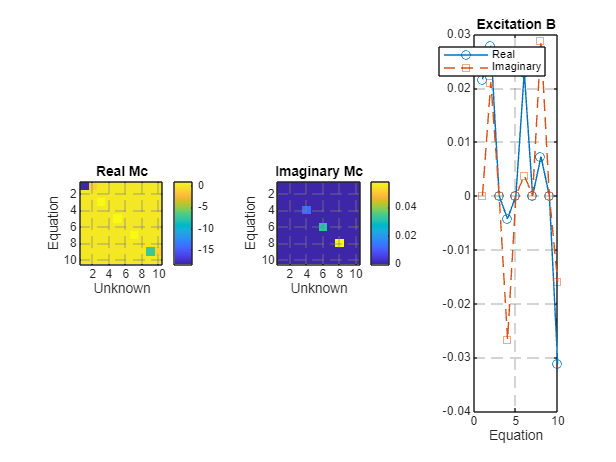


figure('Name','Global circuit system');
tiledlayout(1,3);
nexttile; imagesc(real(Mc)); colorbar; title('Real Mc'); axis equal tight;
xlabel('Unknown'); ylabel('Equation');
nexttile; imagesc(imag(Mc)); colorbar; title('Imaginary Mc'); axis equal tight;
xlabel('Unknown'); ylabel('Equation');
nexttile; plot(1:2*Nc,real(B),'o-',1:2*Nc,imag(B),'s--');
title('Excitation B'); legend('Real','Imaginary'); xlabel('Equation');
style_axes(gcf);

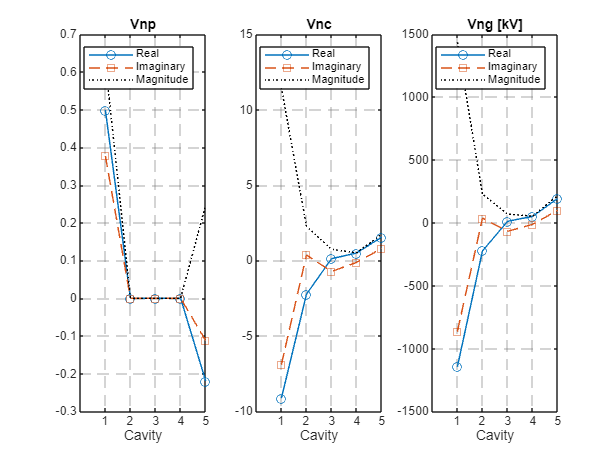


figure('Name','Circuit and gap voltages');
tiledlayout(1,3);
values = {Vnp,Vnc,Vng};
names = {'Vnp','Vnc','Vng [kV]'};
for j=1:3
    nexttile; plot(1:Nc,real(values{j}),'o-',1:Nc,imag(values{j}),'s--',1:Nc,abs(values{j}),'k:');
    title(names{j}); xlabel('Cavity'); xticks(1:Nc);
    legend('Real','Imaginary','Magnitude');
end
style_axes(gcf);

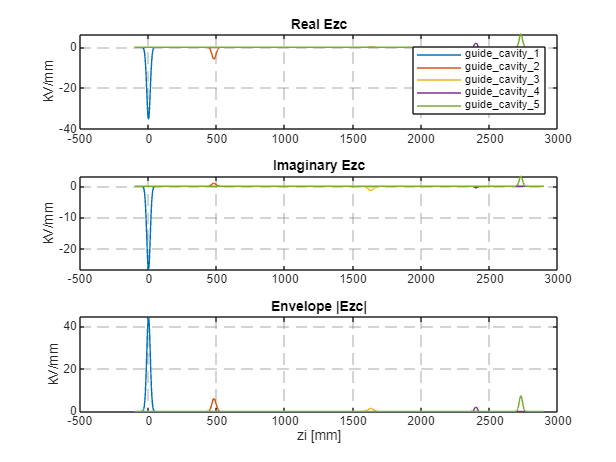


figure('Name','Reconstructed RF field coefficients');
tiledlayout(3,1);
nexttile; plot(zi,real(Ezc)); title('Real Ezc'); ylabel('kV/mm');
legend(S1,'Interpreter','none');
nexttile; plot(zi,imag(Ezc)); title('Imaginary Ezc'); ylabel('kV/mm');
nexttile; plot(zi,abs(Ezc)); title('Envelope |Ezc|'); ylabel('kV/mm'); xlabel('zi [mm]');
style_axes(gcf);

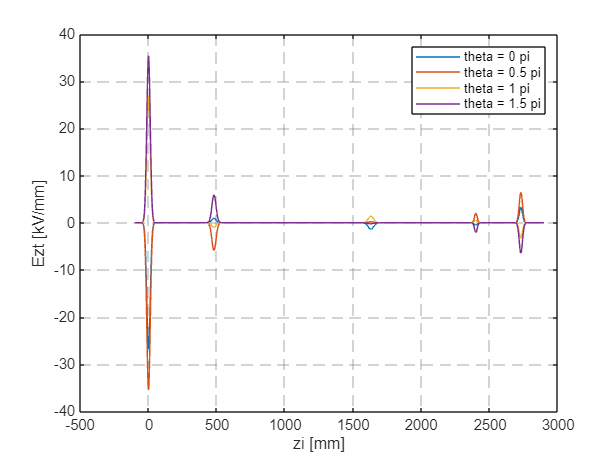


figure('Name','Reconstructed instantaneous RF field');
plot(zi,Ezt); xlabel('zi [mm]'); ylabel('Ezt [kV/mm]');
legend(compose('theta = %.2g pi',theta/pi)); style_axes(gcf);

## 12. TEST ONLY: numerical checks

assert(all(isfinite(temp)) && all(isfinite(Ezc),'all'));
assert(all(abs(Mc*temp-B) <= 1e-12+1e-10*abs(B)));
assert(all(flagVnc == 0));
assert(all(abs(trapz(zi,Ezc,1)-Vng) <= 1e-12+1e-10*abs(Vng)));
Emz_from_C3 = zeros(size(Emz_reconstructed));
for k=1:Nc
    Emz_from_C3(:,nh(k)) = Emz_from_C3(:,nh(k)) + C3(:,k)*Vnc(k)*U0*1000/eta0/I0;
end
assert(all(abs(Emz_from_C3-Emz_reconstructed) <= 1e-12+1e-10*abs(Emz_reconstructed),'all'));
assert(all(abs(abs(1000*Vng).^2-2*Pwall.*Qin.*RtoQ_grid) <= 1e-12+1e-10*abs(1000*Vng).^2));
assert(all(abs(power_scale*abs(Vin*drivefactor).^2-Pin*drivefactor^2) <= 1e-12+1e-10*Pin*drivefactor^2));

Bbeam = zeros(size(B));
Bbeam(2:2:end) = Ibeam.';
Bexternal = B-Bbeam;
external_solution = Mc\Bexternal;
beam_solution = Mc\Bbeam;
four_power_solution = Mc\(2*Bexternal);
assert(all(abs(temp-external_solution-beam_solution) <= 1e-12+1e-10*abs(temp)));
assert(all(abs(four_power_solution-2*external_solution) <= 1e-12+1e-10*abs(four_power_solution)));
off_diagonal = kai-diag(diag(kai));
if ~any(off_diagonal,'all')
    separate = zeros(size(temp));
    for k=1:Nc
        block = 2*k-1:2*k;
        separate(block) = Mc(block,block)\B(block);
        if type(k)==0
            Dk = 1/Qin(k)+2i*(nh(k)*w-w0(k))/w0(k)+2i*kai(k,k);
            expected_Vnc = 2*exp(1i*Lsb(k))*Vin(k)*drivefactor/sqrt(Qext(k))/(Dk+1/Qext(k));
            assert(abs(external_solution(2*k)-expected_Vnc) <= 1e-12+1e-10*abs(expected_Vnc));
        end
    end
    assert(all(abs(temp-separate) <= 1e-12+1e-10*abs(temp)));
end
fprintf('Linear-system residual norm: %.3e\n',norm(Mc*temp-B));

Linear-system residual norm: 1.664e-15


disp('PASS: MATLAB circuit, superposition, power scaling and reconstructed-field checks.');

PASS: MATLAB circuit, superposition, power scaling and reconstructed-field checks.


## 13. Export only this test's MATLAB results

run_id is copied from inputs.mat to detect stale result pairs. No Python result file is read. Save -v7 for scipy.io.loadmat.

save(fullfile(test_directory,'matlab_results.mat'), ...
    'Iz0','I0','U0','s','vetoc','vn1','gama', ...
    'Pinflag','Pin','Vin','flagVnc','Vnp','Vnc','Mc','B', ...
    'w','w0','k0','betae','dz','zi','z','dt','z_mm','e_z','ez','C3', ...
    'IzDC','Iz','Ibeam','Vng','Ezc','Emz_reconstructed','Ezt', ...
    'Pport','Pwall','Pout','RtoQ_grid', ...
    'Nt','Ns','Nc','N','theta','drivefactor','kai','gaman','Lsb','nh','type', ...
    'case_name','beam_transport','cavityname','run_id','-v7');
fprintf('Saved: %s\n',fullfile(test_directory,'matlab_results.mat'));

Saved: C:\Users\lsito\Desktop\PyKlyC\pyKlyC\test\5.cavity_circuit_test\matlab_results.mat


disp('Next: run compare_results.ipynb.');

Next: run compare_results.ipynb.
